close("all"); clear; clc;

vx = 130/3.6;
p = bikeSimToSharp(bigSportsParameters());
sys = sharpMotorcycleStateSpaceFactory(vx,p);

lsys = linearSys(sys.a,sys.b);

load("straight_results.mat");
tf = results(1).Trajectory.Time(end);
ts = tf/3900;
x0 = zeros(8,1);
umax = 34;

options.timeStep = ts;
options.zonotopeOrder = 20;
options.taylorTerms = 10;

params.tFinal = tf;
params.R0 = zonotope(interval(x0,x0));
params.u = results(1).Trajectory.States(end,:);
params.U = zonotope(interval(-umax,umax));
R = reach(lsys,params,options);

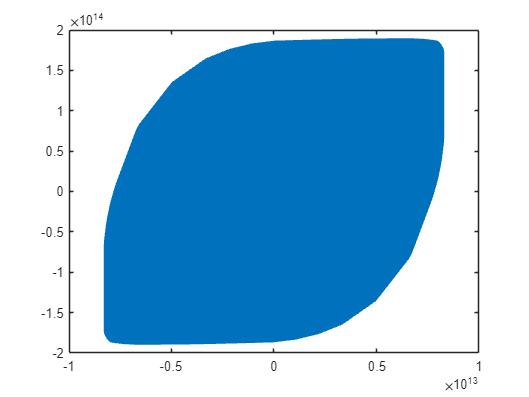

figure; hold on; box on
plot(R,[1,5])
hold off;